# Instituto Tecnológico de Aeronaútica

### Aluno: Eduardo Bezerra Robalinho Dantas da Gama;

### Professor: Dr. Francisco Alex Correia Monteiro

Vetores com os Inputs

xp=[1, 2, 3, 4, 5, 6];
yp=[1.487, 2.958, 5.602, 8.003, 11.452, 13.021];

Análise da correlação dos inputs:

corrcoef(xp,yp);

Plotagem dos dados fornecidos:

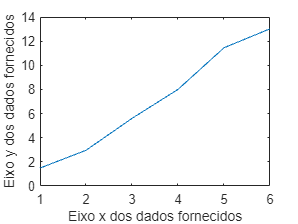

plot(xp,yp)
xlabel('Eixo x dos dados fornecidos');
ylabel('Eixo y dos dados fornecidos');

Número de graus de Liberdade da Função (ordem do polinômio associado ao ajuste):

n=2;

Estrutura da função:

%função potência: y=ax^b
%vetores da forma logaritimizada;
yl=log(yp);
xl=log(xp);

Criação da matriz de regressão linear:

A=regre_matrix(xl,2);

Criação do vetor de termos independentes:

b= independent_vector(xl,yl,2);

Solução da equação com os coeficientes:

%cálculo dos coeficientes:
S=linsolve(A,b);

Função interpolada com os pontos:

f=@(x)exp(S(1,1))*x.^(S(2,1));

Plotagem dos pontos com a função interpolada:

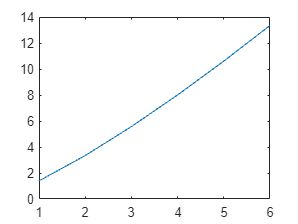

plot(xp,f(xp))

Matriz de regressão linear

function A=regre_matrix(x,n)
A=zeros(n,n);
for i=1:n
    for j=1:n
        A(i,j)=sum(x.^(abs(j+i)-2)); 
    end
end
end

Vetor de termos independentes

function b= independent_vector(x,y,n)
b=zeros(n,1);
for i=1:n
b(i,1)=sum(x.^(i-1).*y);
end
end